# Machine Learning Online Class

## Initialization

clear ; close all; clc

## ================== Part 1: Load Example Dataset ===================

fprintf('Visualizing example dataset for outlier detection.\n\n');

Visualizing example dataset for outlier detection.



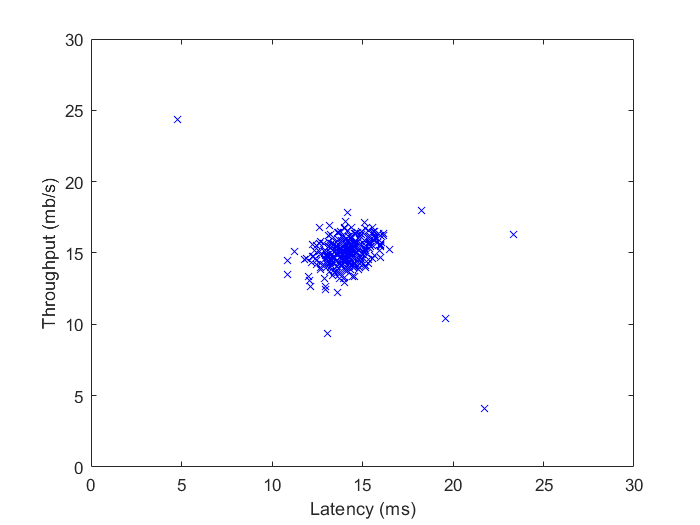


%  The following command loads the dataset. You should now have the
%  variables X, Xval, yval in your environment
load('ex8data1.mat');

%  Visualize the example dataset
plot(X(:, 1), X(:, 2), 'bx');
axis([0 30 0 30]);
xlabel('Latency (ms)');
ylabel('Throughput (mb/s)');


% fprintf('Program paused. Press enter to continue.\n');
% pause

## ================== Part 2: Estimate the dataset statistics ===================

fprintf('Visualizing Gaussian fit.\n\n');

Visualizing Gaussian fit.



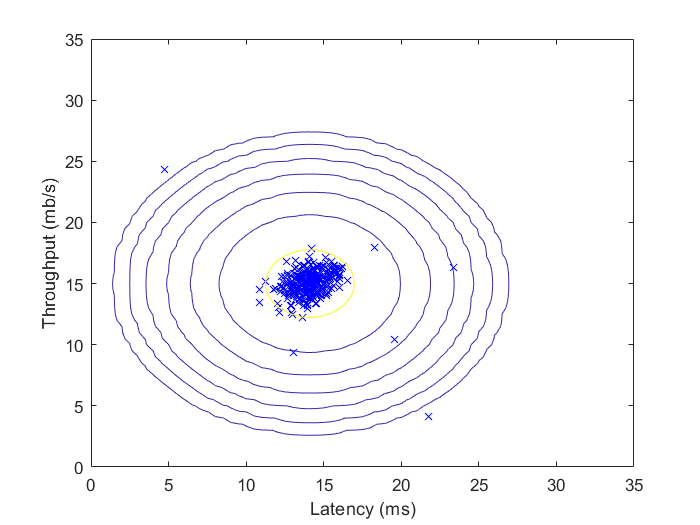


%  Estimate my and sigma2
[mu sigma2] = estimateGaussian(X);

%  Returns the density of the multivariate normal at each data point (row) 
%  of X
p = multivariateGaussian(X, mu, sigma2);

%  Visualize the fit
visualizeFit(X,  mu, sigma2);
xlabel('Latency (ms)');
ylabel('Throughput (mb/s)');


% fprintf('Program paused. Press enter to continue.\n');
% pause;

## ================== Part 3: Find Outliers ===================

pval = multivariateGaussian(Xval, mu, sigma2);

[epsilon F1] = selectThreshold(yval, pval);
fprintf('Best epsilon found using cross-validation: %e\n', epsilon);

Best epsilon found using cross-validation: 8.990853e-05


fprintf('Best F1 on Cross Validation Set:  %f\n', F1);

Best F1 on Cross Validation Set:  0.875000


fprintf('   (you should see a value epsilon of about 8.99e-05)\n');

   (you should see a value epsilon of about 8.99e-05)


fprintf('   (you should see a Best F1 value of  0.875000)\n\n');

   (you should see a Best F1 value of  0.875000)



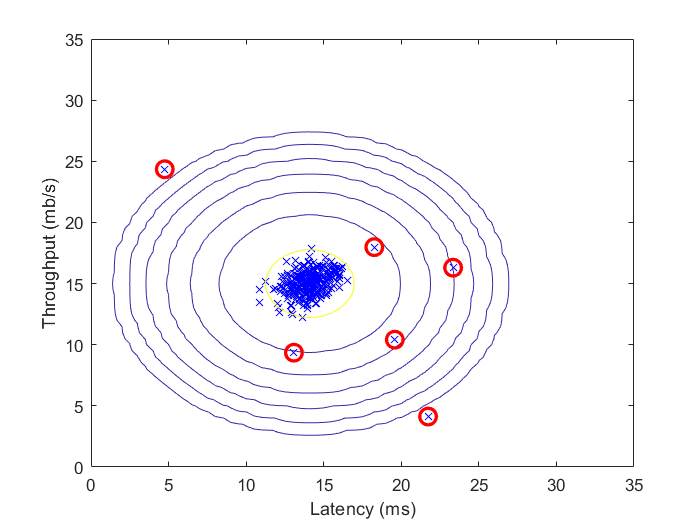


%  Find the outliers in the training set and plot the
outliers = find(p < epsilon);

%  Draw a red circle around those outliers
hold on
plot(X(outliers, 1), X(outliers, 2), 'ro', 'LineWidth', 2, 'MarkerSize', 10);
hold off


% fprintf('Program paused. Press enter to continue.\n');
% pause;

## ================== Part 4: Multidimensional Outliers ===================

%  Loads the second dataset. You should now have the
%  variables X, Xval, yval in your environment
load('ex8data2.mat');

%  Apply the same steps to the larger dataset
[mu sigma2] = estimateGaussian(X);

%  Training set 
p = multivariateGaussian(X, mu, sigma2);

%  Cross-validation set
pval = multivariateGaussian(Xval, mu, sigma2);

%  Find the best threshold
[epsilon F1] = selectThreshold(yval, pval);

fprintf('Best epsilon found using cross-validation: %e\n', epsilon);

Best epsilon found using cross-validation: 1.377229e-18


fprintf('Best F1 on Cross Validation Set:  %f\n', F1);

Best F1 on Cross Validation Set:  0.615385


fprintf('   (you should see a value epsilon of about 1.38e-18)\n');

   (you should see a value epsilon of about 1.38e-18)


fprintf('   (you should see a Best F1 value of 0.615385)\n');

   (you should see a Best F1 value of 0.615385)


fprintf('# Outliers found: %d\n\n', sum(p < epsilon));

# Outliers found: 117

